# Indirect PGAC with regularization

% This is the code of indirect PGAC with regularization. 

## Model

clear 
n = 3; % state dimension
m = 3; % input dimension 
A = [1.01, 0.01, 0;
0.01, 1.01, 0.01;
0, 0.01, 1.01;];
B = eye(m,m);
Q = eye(n,n);
R = 0.001*eye(m,m); 
I = eye(n,n);   % identity matrix

## Parameter

num = 2000; % total number of time steps
eta = 0.02; % constant stepsize for the projected gradient descent 
delta = 1; % noise level
gamma = 1; % excitation level
T = 20; % the length of offline data (T >= n+m)
lambda = 0.1; % robust regularizer

## Optimal solution

[~,P,E] = dlqr(A,B,Q,R); % solving the model-based LQR problem
J_opt = trace(P); % optimal LQR cost

## Initialization

% The following initial data is generated using "Data_generate.mlx". 
load offline_noise.mat
load online_noise.mat
load probing_noise.mat
load offline_input.mat

K = zeros(m,n,num); % inital policy (Here, we use zero policy since the system is open-loop stable.)
J = zeros(num-1,1); % the LQR cost

% generate offline data 
W = delta*offline_noise; % offline noise data matrix
X0 = zeros(n, T); % initialize offline state data matrix
X0 (:,1) = 0;
U0 = offline_input;
for i = 1:T-1
    X0(:,i+1) = A*X0(:,i) + B*U0(:,i) + W(:,i);
end

## Online

Covinv = zeros(n+m,n+m,num); % inverse of the covariance matrix
psi = zeros(n+m,num); % pile up the input and state vector

% initial policy solved from the SDP with offline data
K(:,:,1) = sdp(m,n,T-1,Q,R,lambda,X0(:,1:(T-1)),U0(:,1:(T-1)),X0(:,2:T));
%K(:,:,1) = zeros(m,n); 

x = zeros(n,num);
u = zeros(m,num);
x(:,1) = X0(:,T);
u(:,1) = U0(:,T);
w = delta*online_noise; % random process noise
e = gamma*probing_noise; % random probing noise

tic
for t = 1:num-1
    % compute the LQR cost (just for the plot!)
    P_true = dlyap((A+B*K(:,:,t))', Q + K(:,:,t)'*R*K(:,:,t));
    J(t) = trace(P_true);
    
    % collect new data 
    x(:,t+1) = A*x(:,t) + B*u(:,t) + w(:,t); 
    X = [X0(:,1:(T-1)),x];
    U = [U0(:,1:(T-1)),u];
    D = [U(:,1:T-1+t);X(:,1:T-1+t)];
    
    % rank-one update of the (inverse) covariance
    psi(:,t) = [u(:,t); x(:,t)]; % pile up the input and state vector
    if t == 1
        Covinv(:,:,t) = inv(1/(T-1+t)*(D*D')); 
        U_bar = 1/(T-1+t)*U(:,1:T-1+t)*D';
        X_bar = 1/(T-1+t)*X(:,1:T-1+t)*D';
        X1_bar = 1/(T-1+t)*X(:,2:T+t)*D';
    else
        U_bar = (1-1/(T-1+t))*U_bar + 1/(T-1+t)*u(:,t)*psi(:,t)';
        X_bar = (1-1/(T-1+t))*X_bar + 1/(T-1+t)*x(:,t)*psi(:,t)';
        X1_bar = (1-1/(T-1+t))*X1_bar + 1/(T-1+t)*x(:,t+1)*psi(:,t)';
        Covinv(:,:,t) = (1/(1-1/(T-1+t)))*(Covinv(:,:,t-1) - 1/(T-1+t)*(Covinv(:,:,t-1)*psi(:,t)*psi(:,t)'*Covinv(:,:,t-1))/(1-1/(T-1+t) + 1/(T-1+t)*psi(:,t)'*Covinv(:,:,t-1)*psi(:,t))); 
    end
    
    % Update of the model estimate
    Model = X1_bar*Covinv(:,:,t);
    B_hat = Model(:,1:m);
    A_hat = Model(:,m+1:m+n);
     
    % time-varying regularization coefficient
    lambda_t = lambda*(sqrt(T)/sqrt(t+T));

    % Computation of the gradient 
    Phi_inv = Covinv(:,:,t); 
    Q_lambda = Q + lambda_t* Phi_inv(m+1:m+n, m+1:m+n);
    R_lambda = R + lambda_t* Phi_inv(1:m, 1:m);
    P = dlyap((A_hat + B_hat*K(:,:,t))', Q_lambda + K(:,:,t)'*R_lambda*K(:,:,t) + lambda_t*Phi_inv(m+1:m+n, 1:m)*K(:,:,t) + lambda_t*K(:,:,t)'*Phi_inv(m+1:m+n, 1:m)' );
    Sigma = dlyap((A_hat + B_hat*K(:,:,t)), eye(n,n));
    nabla_K = 2*((R+B_hat'*P*B_hat)*K(:,:,t)+B_hat'*P*A_hat + lambda_t*Phi_inv(m+1:m+n, 1:m)')*Sigma;
 
    % Policy update
    K(:,:,t+1) = K(:,:,t) - eta*nabla_K;

    % Generate the input
    u(:,t+1) = K(:,:,t+1)*x(:,t+1)+ e(:,t+1); % update the control input
end
toc

历时 0.256251 秒。


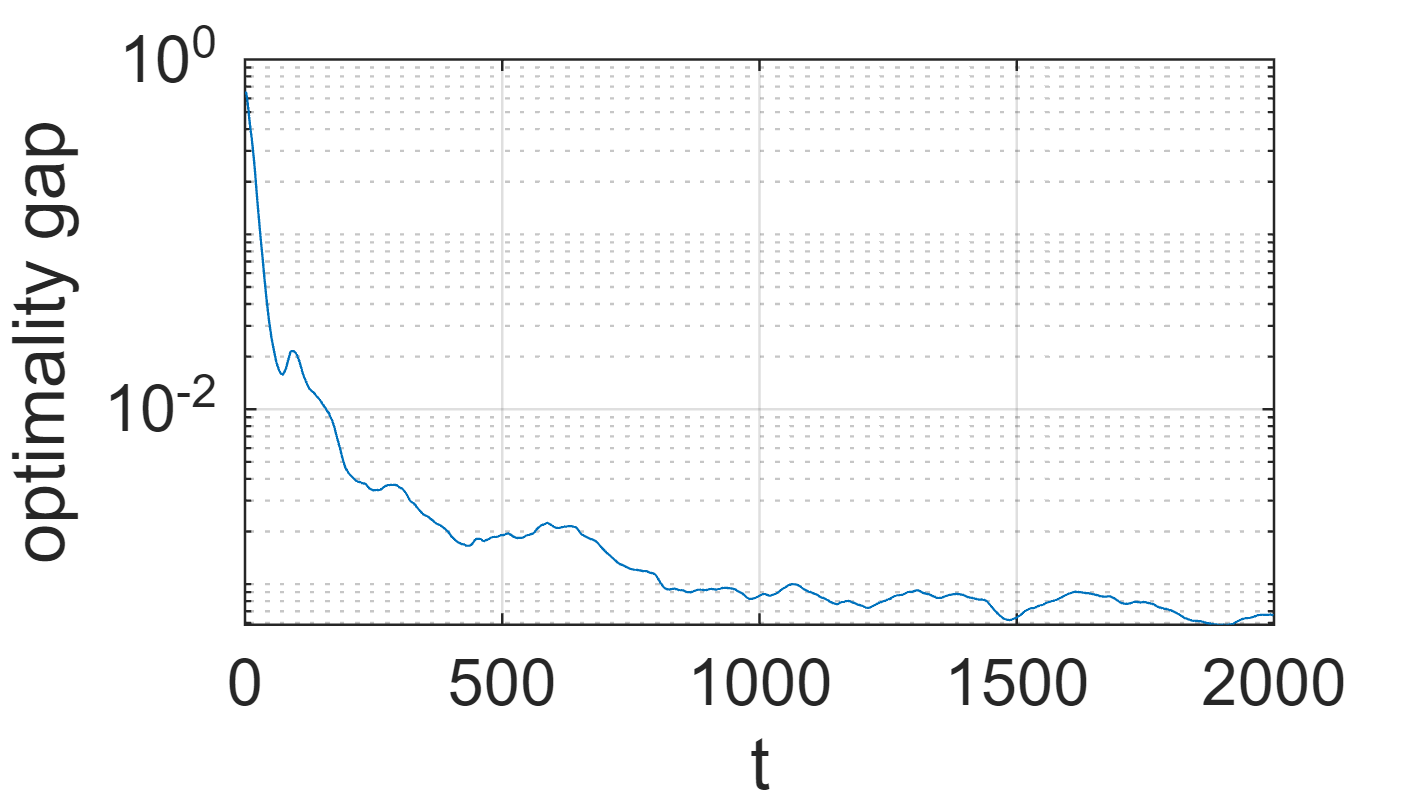


% plot
xias = 1:num-1;
error = (J - J_opt)/J_opt;
semilogy(xias, error)
xlabel('t','FontSize',14)
ylabel('optimality gap','FontSize',14)
grid on
set(gca,'FontSize',14);
set(gcf,'unit','centimeters','position',[1,2,14,8])